# Lab session II:

## Intro:

On this Laboratory session we are going to work with the different attitude representations seen in class. 

- Exercise 1: 1 point. To be delivered before the end of the session.

- Exercise 2: 2 points

- Exercise 3: 2.5 points

- Exercise 4: 2 points

- Exercise 5: 2.5 points

**Lab rules:**

- Always respect the delivery dates

- Use the templates when provided and DO NOT MODIFY THE FILE NAMES OR THE FUNCTION NAMES

- Verify that your code works before submit

- Always upload the files in a .zip with the name structure:  * Surname_Name.zip*

- Cheating is not allowed and will be firmly punished with a final mark of 0

This assignment is due to November 24th before 23:45 p.m.

## Exercise 1:

**Create** and **test** a function named **Eaa2rotMat **that given euler axis/angle information returns the respective rotation matrix.

Perform and show the result of the next verifications:

- Calculate the R* determinant of the resulting rotation matrix 

u1 = [2,3,4]';
R1 = Eaa2rotMat(30,u1);
d = det(R1);

El determinante es uno puesto que una matriz de rotación es una transformación lineal y mantiene las distancias, los angulos y el volumen.

- Compare the transpose and the inverse of the resulting matrix

R1;
T = R1';
I = inv(R1);
C1 = T-I;

Las dos matrices son prácticamente la misma, si las restamos dan un error de magnitud e-16, así que las consideraremos como iguales. Esto significa que la matriz es efectivamente una matriz de rotación ya que es ortonormal y los vectores que la forman son linealmente independientes. 

- Using the output matrix, transform a vector parallel to the axis of rotation. 

p = 2*u1;
Q = R1*p;

What happens?

    Al intentar rotar un vector usando una matriz de rotación que rota un vector respecto a un eje y ese eje es paralelo a nuestro vector es como si intentaramos rotar ese vector respecto si mismo y por tanto no rota y el esultado es el mismo vector. 

- Using the output matrix, transform a vector perpendicular to the axis direction. Calculate the scalar product between the original vector (the unrotated vector) and the rotated one.

u2 = [1,1,-2];
t1 = R1 * u2';
s = dot(u2,t1);

 What you observe? (Hint: Think about the scalar product definition)

Observamos que el vector dependiendo de la matriz de rotación y del eje dirección.

## Exercise 2:

The matrix 

axisM = (rand(3,100)-.5);

 contains 100 random (non-unit) axis. While 

theta = linspace(0,6*pi,100);

 is a vector with orderer angles.

Every pair, axisM(:,q) and theta(q) represents the attitude of a body.

- For every pair (in a for loop) calculate the rotation matrix and store the value of its trace in a vector.

t2 = zeros(1,100);
for i = 1:100
    R2 = Eaa2rotMat(theta(i),axisM(:, i));
    t2(1,i) = trace(R2);
end

- Make a plot of the vector that you have obtained vs the theta angle. Explain why would you expect this result.

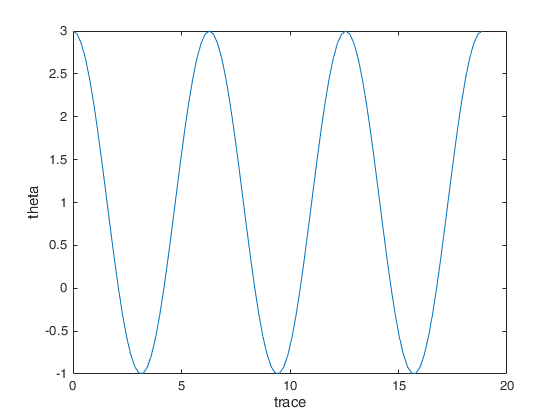

plot(theta, t2);
ylabel('theta');
xlabel('trace');

**Da igual el  eje respecto al que giremos. A medida que vaya aumentando el ángulo, la traza de la matriz disminuirá.**

**Además, en el gráfico observamos que el valor de theta tiene una frecuencia de 2n***π **respecto a la traza. Por tanto, el valor de theta es igual a 3 cuando la traza vale 2n***π**, y es igual a -1 cuando la traza es 2n***π-π.

Dado que el ángulo y la traza de la matriz de rotación que forma son dependientes crean una función con forma de onda cosinusoidal.

## Exercise 3:

**Create** and **test** a function named **rotMat2Eaa** that given a rotation matrix returns its respective euler principal axis and angle.

Perform and show the results of the next verifications:

- Use the function on exercise 1 to create a rotation matrix from Euler axis information and ensure that the new function performs the inverse mapping correctly.

R30 = Eaa2rotMat(pi,[0,1,0]');
[a3,u3] = rotMat2Eaa(R30);

- What happens if you try to extract the angle and axis of the next matrices? What they have in common? 


$$\mathbf{R}_1 = \left( \begin{array}{ccc} 1 &0 &0\\ 0 &1&0 \\0 &0 & 1\end{array}\right),$$

$$\mathbf{R}_2 = \left( \begin{array}{ccc} -\frac{1}{3} &\frac{2}{3} &\frac{2}{3}\\ \frac{2}{3} &-\frac{1}{3}&\frac{2}{3} \\\frac{2}{3} &\frac{2}{3} & -\frac{1}{3}\end{array}\right),$$

$$\mathbf{R}_3 = \left( \begin{array}{ccc} 0 &0 &-1\\ 0 &-1&0 \\-1 &0 & 0\end{array}\right),$$


Al intentar encontrar la matriz que nos dará el eje nos encontramos que no podemos dividir entre el seno de 0 o de 180 ya que es 0, y por ello Matlab nos devuelve ceros. Esto significa que en este caso no podemos saber la matriz ni tampoco el eje.

- Propose a solution for the past problem, **implement it** and verify that it works using the past matrices

Solution here :  En el caso de que el seno del ángulo sea igual a 0 devolvemos un eje aleatorio puesto que puede rotar alrededor de cualquier eje, en caso contrario actuamos con normalidad.

R31 = [1, 0, 0;
       0, 1, 0;
       0 , 0, 1];
R32 = [-1/3, 2/3, 2/3;
       2/3, -1/3, 2/3;
       2/3, 2/3, -1/3];
R33 = [0, 0, -1;
       0, -1, 0;
       -1, 0, 0];
[a31,u31] = rotMat2Eaa(R31);
[a32,u32] = rotMat2Eaa(R32);
[a33,u33] = rotMat2Eaa(R33);


## Exercise 4

**Find the rotation vectors** that rotates the cube to reach the next orientations:

- The green face points in the positive z direction and the orange face in the -y direction

-     $$r_1 = $$ ( 0,pi/2,0 )$$^T$$

- The orange face points in the -z direction and the blue face into the +y direction

-     $$r_2 = $$ ( 1.2093, 1.2093 , 1.2093)$$^T$$

- The red face points on the -x direction and the blue face into the -y direction

-     $$r_3 = $$ ( -pi/2, pi/2,0 )$$^T$$

Use the function of the exercise 1 transform the orientation of the cube given by M for **every** of the previous cases and use the function  Cubeplot to  verify your previous answers

M = [-1  -1 1;   %Node 1
    -1   1 1;   %Node 2
    1   1 1;   %Node 3
    1  -1 1;   %Node 4
    -1  -1 -1;  %Node 5
    -1   1 -1;  %Node 6
    1   1 -1;  %Node 7
    1  -1 -1]; %Node 8

R = eye(3);
R41 = Eaa2rotMat(pi/2,[0;1;0]);
r41 = pi/2 * [0;1;0];

R421 = Eaa2rotMat(pi/2,[1;0;0]);
R422 = Eaa2rotMat(pi/2,[0;0;1]);
R42 = R422*R421;
[a42,u42] = rotMat2Eaa(R42)

a42 = 2.0944

u42 =     0.5774    0.5774    0.5774


r42 = a42 * u42;

R431 =  Eaa2rotMat(pi/2,[0;0;1]);
R432 = Eaa2rotMat(pi,[0;1;0]);
R43 = R431 * R432;
[a43,u43] = rotMat2Eaa(R43)

a43 = 3.1416

u43 =    -0.5000    0.5000         0


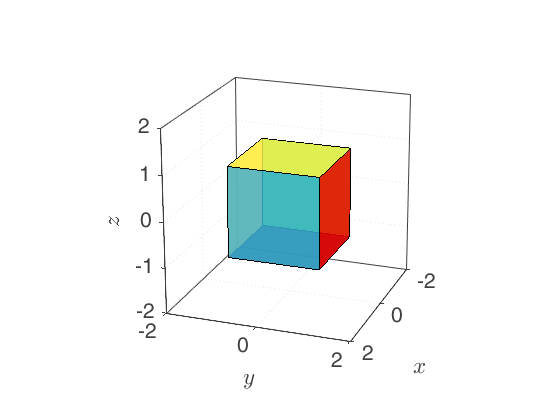

r43 = a43 * u43;

%R = R41;
%R = R42;
%R = R43;
M_mod = (R*M')';
Cubeplot(M_mod);

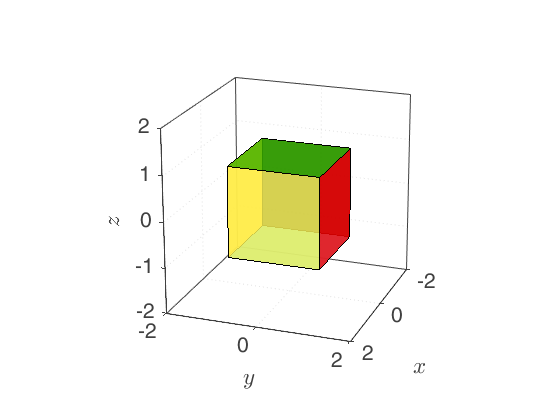

M_mod1 = (R41*M')';
Cubeplot(M_mod1);

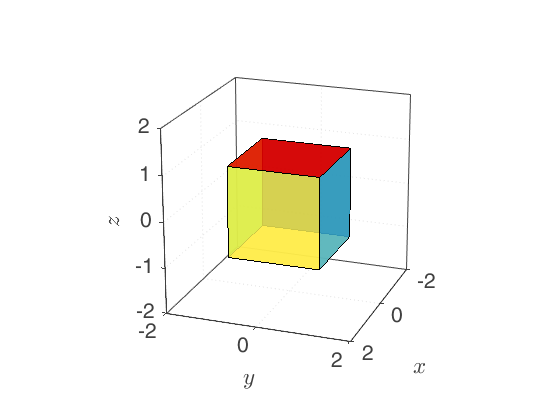

M_mod2 = (R42*M')';
Cubeplot(M_mod2);

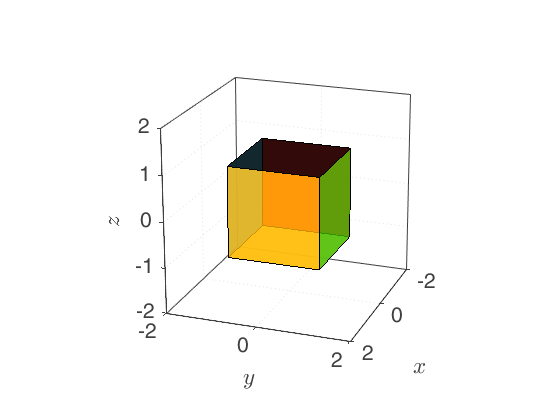

M_mod3 = (R43*M')';
Cubeplot(M_mod3);

## Exercise 5

**Create** and **test **a function named **eAngles2rotM **that given a set of euler angles $(\varphi, \theta, \psi)$, return its respective rotation matrix.

- Calculate the determinant of the resulting rotation matrix 

R51 = eAngles2rotM(1,1,1);
D5 = det(R51);

- Compare the transpose and the inverse of the resulting matrix

T5 = R51';
I5 = inv(R51);
C5 = T5 - I5;

**Create also** a function named **rotM2eAngles **that given a rotation matrix return its respective euler angles

- Ensure that the case for which theta = pi/2 + k*pi with k=1,2,.. is well implemented

Rpi = eAngles2rotM(1,pi * 0.5,3)

Rpi =     0.0000    0.9093   -0.4161
    0.0000   -0.4161   -0.9093
   -1.0000    0.0000   -0.0000


[yawpi, pitchpi, rollpi] = rotM2eAngles(Rpi) 

yawpi = 1.4161

pitchpi = 1.5708

rollpi = 0

- Use the first function of this exercise to create a rotation matrix from a set of euler angles and ensure that the new function performs the inverse mapping correctly.

R52 = eAngles2rotM(1,2,3)

R52 =    -0.2248    0.9024   -0.3676
   -0.3502   -0.4269   -0.8337
   -0.9093   -0.0587    0.4120


[yaw5,pitch5,roll5] = rotM2eAngles(R52)

yaw5 = -2.1416

pitch5 = 1.1416

roll5 = -0.1416